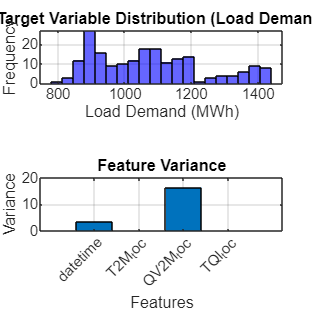

% Load dataset
data = readtable('C:\Users\swaru\Downloads\continuous dataset.csv');

% Extract features (X) and target variable (y)
feature_names = {'datetime', 'T2M_toc', 'QV2M_toc', 'TQl_toc', 'W2M_toc'};
X = [ data.T2M_toc, data.QV2M_toc, data.W2M_toc, data.TQL_toc];
y = data.nat_demand;  % Target variable (Load Demand)
% Create figure with increased height for better spacing
figure('Position', [100, 100, 800, 800]); % Increased height to 800 for better spacing

% Target Variable Distribution (Load Demand)
subplot(2,1,1); % Two rows, one column → First graph
histogram(y, 20, 'FaceColor', 'b');
title('Target Variable Distribution (Load Demand)');
xlabel('Load Demand (MWh)'); ylabel('Frequency'); grid on;

% Feature Variance
subplot(2,1,2); % Two rows, one column → Second graph
bar(var(X));
title('Feature Variance');
xlabel('Features'); ylabel('Variance'); grid on;
set(gca, 'XTickLabel', feature_names, 'XTickLabelRotation', 45);




% === Split Dataset into Training & Testing (80%-20%) ===
cv = cvpartition(size(data, 1), 'HoldOut', 0.2);

Unrecognized function or variable 'data'.

X_train = X(training(cv), :);
y_train = y(training(cv), :);
X_test = X(test(cv), :);
y_test = y(test(cv), :);

fprintf('Dataset split into 80%% training and 20%% testing.\n');


% Z-score Normalization (Standardization)
[X_train_scaled, mu, sigma] = zscore(X_train);
X_test_scaled = (X_test - mu) ./ sigma;

%% Enhanced SVM Model with Hyperparameter Optimization
svm_model = fitrsvm(X_train_scaled, y_train, 'KernelFunction', 'rbf', ...
    'OptimizeHyperparameters', 'auto', 'HyperparameterOptimizationOptions', ...
    struct('AcquisitionFunctionName', 'expected-improvement-plus', 'ShowPlots', true));

% Predict using SVM
y_pred_svm = predict(svm_model, X_test_scaled);

% Performance Metrics
mse_svm = mean((y_test - y_pred_svm).^2);
mae_svm = mean(abs(y_test - y_pred_svm));
ss_tot = sum((y_test - mean(y_test)).^2);
ss_res_svm = sum((y_test - y_pred_svm).^2);
r2_svm = 1 - (ss_res_svm / ss_tot);

% Display Metrics
fprintf('\nSVM Model Performance:\n');
fprintf('Mean Squared Error (MSE): %.4f\n', mse_svm);
fprintf('Mean Absolute Error (MAE): %.4f\n', mae_svm);
fprintf('R-Squared (R²): %.4f\n', r2_svm);

% Save results to a text file
fileID = fopen('svm_results.txt', 'w');
fprintf(fileID, 'SVM Model Performance:\n');
fprintf(fileID, 'Mean Squared Error (MSE): %.4f\n', mse_svm);
fprintf(fileID, 'Mean Absolute Error (MAE): %.4f\n', mae_svm);
fprintf(fileID, 'R-Squared (R²): %.4f\n', r2_svm);
fclose(fileID);

%% Plot Results
figure;
plot(y_test, 'b', 'LineWidth', 1.5); hold on;
plot(y_pred_svm, 'r--', 'LineWidth', 1.5);
title('SVM Model Prediction');
legend({'True Load', 'Predicted Load'});
xlabel('Sample'); ylabel('Load Demand');
grid on;

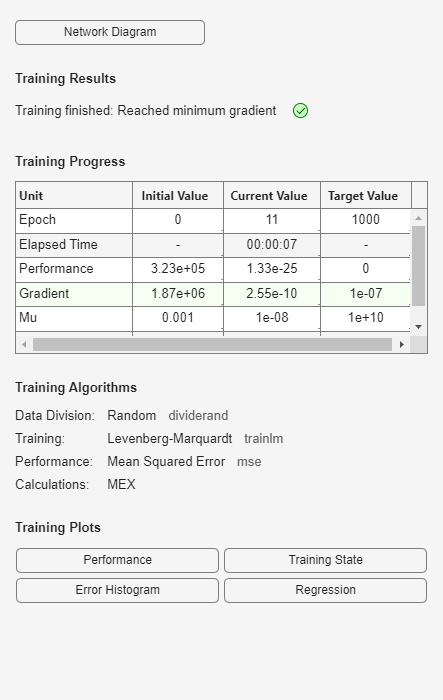


%% ANN Model
ann_net = feedforwardnet([64, 32]); % Neural Network with 2 hidden layers
ann_net = train(ann_net, X_train_scaled', y_train'); % Train ANN

y_pred_ann = ann_net(X_test_scaled'); % Predict using ANN
mse_ann = mean((y_test - y_pred_ann').^2); % Calculate Mean Squared Error (MSE)
fprintf('ANN Model Mean Squared Error: %.4f\n', mse_ann);

ANN Model Mean Squared Error: 12041.1215


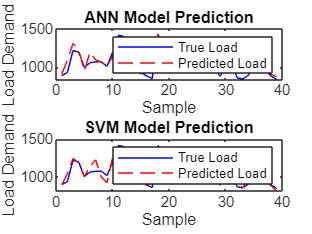



%% Plot Results
figure;
subplot(2, 1, 1);
plot(y_test, 'b'); hold on;
plot(y_pred_ann, 'r--');
title('ANN Model Prediction');
legend({'True Load', 'Predicted Load'});
xlabel('Sample'); ylabel('Load Demand');

subplot(2, 1, 2);
plot(y_test, 'b'); hold on;
plot(y_pred_svm, 'r--');
title('SVM Model Prediction');
legend({'True Load', 'Predicted Load'});
xlabel('Sample'); ylabel('Load Demand');

|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |  Standardize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |      10.221 |     0.11307 |      10.221 |      10.221 |      0.30751 |       236.01 |      0.36275 |         true |
|    2 | Best   |      10.219 |    0.035804 |      10.219 |       10.22 |      0.29323 |    0.0010759 |       815.53 |        false |
|    3 | Best   |      9.0241 |    0.036146 |      9.0241 |      9.0995 |       676.64 |       1.6097 |       4.9791 |        false |
|    4 | Accept |      10.219 |    0.034601 |      9.0241 |   

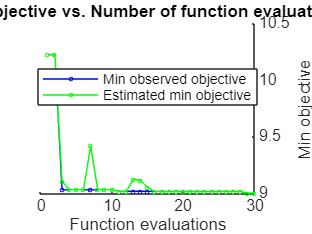

%% Enhanced SVM Model with Hyperparameter Optimization
svm_model = fitrsvm(X_train_scaled, y_train, 'KernelFunction', 'rbf', ...
    'OptimizeHyperparameters', 'auto', 'HyperparameterOptimizationOptions', ...
    struct('AcquisitionFunctionName', 'expected-improvement-plus', 'ShowPlots', true));


% Predict using SVM
y_pred_svm = predict(svm_model, X_test_scaled);

% Performance Metrics
mse_svm = mean((y_test - y_pred_svm).^2);
mae_svm = mean(abs(y_test - y_pred_svm));
ss_tot = sum((y_test - mean(y_test)).^2);
ss_res_svm = sum((y_test - y_pred_svm).^2);
r2_svm = 1 - (ss_res_svm / ss_tot);

% Display Metrics
fprintf('\nSVM Model Performance:\n');


SVM Model Performance:


fprintf('Mean Squared Error (MSE): %.4f\n', mse_svm);

Mean Squared Error (MSE): 7337.9709


fprintf('Mean Absolute Error (MAE): %.4f\n', mae_svm);

Mean Absolute Error (MAE): 64.4476


fprintf('R-Squared (R²): %.4f\n', r2_svm);

R-Squared (R²): 0.7659


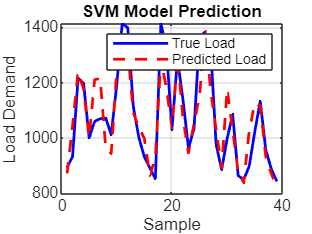


%% Plot Results
figure;
plot(y_test, 'b', 'LineWidth', 1.5); hold on;
plot(y_pred_svm, 'r--', 'LineWidth', 1.5);
title('SVM Model Prediction');
legend({'True Load', 'Predicted Load'});
xlabel('Sample'); ylabel('Load Demand');
grid on;

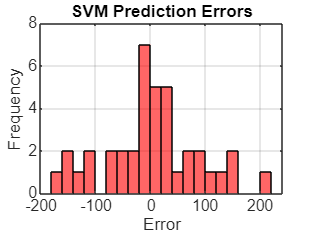


%% Histogram of Errors
figure;
histogram(y_test - y_pred_svm, 20, 'FaceColor', 'r');
title('SVM Prediction Errors');
xlabel('Error'); ylabel('Frequency'); grid on;


%% Save Model for Deployment
save('svm_model.mat', 'svm_model', 'mu', 'sigma');


% Predict using trained ANN
y_pred_ann = ann_net(X_test_scaled'); % ANN expects input in column format
y_pred_ann = y_pred_ann'; % Convert output back to row format

% Performance Metrics
mse_ann = mean((y_test - y_pred_ann).^2);
mae_ann = mean(abs(y_test - y_pred_ann));
r2_ann = 1 - sum((y_test - y_pred_ann).^2) / sum((y_test - mean(y_test)).^2);

% Display Results
fprintf('\nANN Model Performance:\n');


ANN Model Performance:


fprintf('Mean Squared Error (MSE): %.4f\n', mse_ann);

Mean Squared Error (MSE): 12041.1215


fprintf('Mean Absolute Error (MAE): %.4f\n', mae_ann);

Mean Absolute Error (MAE): 80.6701


fprintf('R-Squared (R²): %.4f\n', r2_ann);

R-Squared (R²): 0.6159


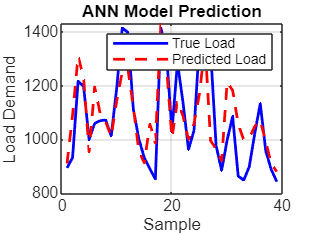


% Plot ANN Predictions vs. Actual Load
figure;
plot(y_test, 'b', 'LineWidth', 1.5); hold on;
plot(y_pred_ann, 'r--', 'LineWidth', 1.5);
title('ANN Model Prediction');
legend({'True Load', 'Predicted Load'});
xlabel('Sample'); ylabel('Load Demand');
grid on;


% Save ANN Model
save('ann_model.mat', 'ann_net', 'mu', 'sigma');

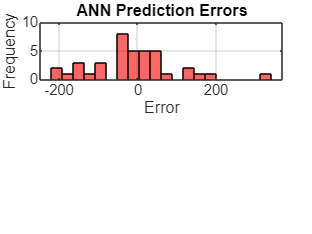

%% Histogram Comparison of ANN Predictions
figure;

% Histogram of ANN Prediction Errors
subplot(2,1,1);
histogram(y_test - y_pred_ann, 20, 'FaceColor', 'r');
title('ANN Prediction Errors');
xlabel('Error'); ylabel('Frequency'); grid on;

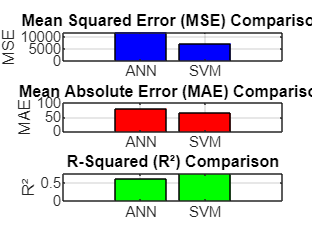

%% Compute Performance Metrics
mse_values = [mse_ann, mse_svm];
mae_values = [mae_ann, mae_svm];
r2_values = [r2_ann, r2_svm];

model_names = {'ANN', 'SVM'};

% Bar Graph for MSE, MAE, and R² Comparison
figure;

% MSE Comparison
subplot(3,1,1);
bar(mse_values, 'FaceColor', 'b');
title('Mean Squared Error (MSE) Comparison');
xticklabels(model_names);
ylabel('MSE'); grid on;

% MAE Comparison
subplot(3,1,2);
bar(mae_values, 'FaceColor', 'r');
title('Mean Absolute Error (MAE) Comparison');
xticklabels(model_names);
ylabel('MAE'); grid on;

% R² Comparison
subplot(3,1,3);
bar(r2_values, 'FaceColor', 'g');
title('R-Squared (R²) Comparison');
xticklabels(model_names);
ylabel('R²'); grid on;